# Lights spiral

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'lights_spiral.pov', 'image_file', 'lights_spiral.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 28, 'location', [22 18 -5], 'look_at', [0 0 4.5], 'type', 'perspective');
    
    % Light
    pl.light('location',  [10 -10 10], 'color', [1 1 1]);
    
    % Create spiral
    nmarks = 150;
    distance = 6.5

distance = 6.5000

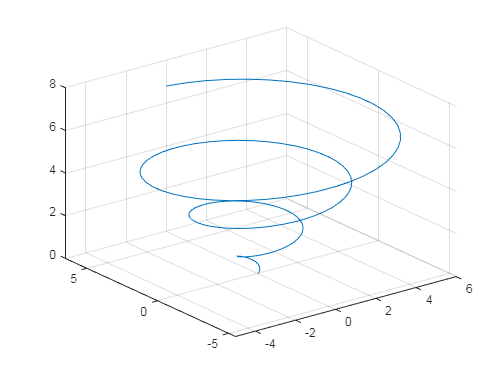

    r = linspace(0,1,nmarks);
    theta = linspace (0, distance * pi, nmarks);
    x = r.*cos(theta) * distance;
    y = r.*sin(theta) * distance;
    z = theta / 3;
    
    % Display preview
    figure(1)
    plot3(x, y, z)
    grid on

    for n = 1:nmarks
        g =  (n / nmarks) / 1.5;
        pl.sphere('position', [x(n) y(n) z(n)], 'radius', 0.2, 'texture', 'Dark_Green_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [x(n) y(n) z(n)], 'color', [g 1-g g]);
    end
    
pl.scene_end();

#### Render and display

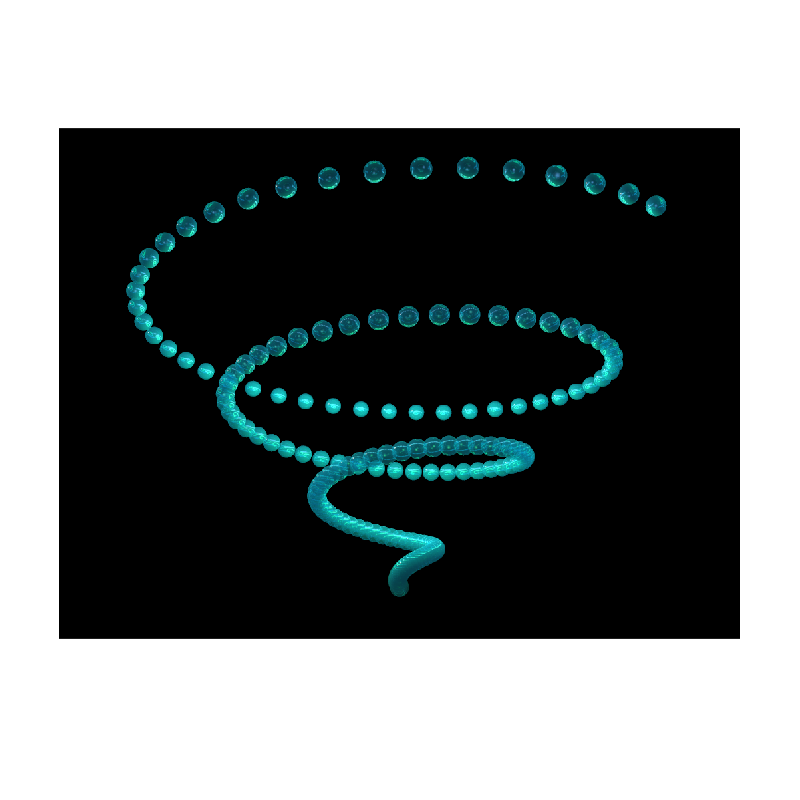

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 647.978738 seconds.
